clear variables;
addPath;

%tempo reduction param
para.kF = 20;
para.redL = 5;
para.reduct = false;

%kernel setting
para.kernel = .2;

%ACA param
para.nMi = 5;
para.nMa = 10;
para.ini='r';
para.k=6;
para.nIni=1;

%HACA param
para.haca = false;
if para.haca 
    para2 = para;
    para2.nMi = 3;
    para2.nMa = 8;
    para2.k=4;
    para2.nIni=10;
    paraH = [para para2];
end

%output path
out_path = './output/6/';
mkdir(out_path);


%select cluster num
% sel_num = 2;

## PSR data

path = '../feat/PSR/2.csv';
X = table2array(readtable(path))';
y = X(16,:);
X(16,:) = [];

% ground truth
yG = onehotencode(y, 1,'ClassNames', unique(y));
GTs = 1;
GTG = yG(:,1);
pre = y(1);
for i =2:size(y,2)
    if pre~=y(i)
        GTs = [GTs i];
        GTG = [GTG yG(:,i)];
    end
    pre = y(i);
end
GTs = [GTs size(y,2)+1];


K = conKnl(conDist(X, X),para.kernel);
seg = segIniR(K, para);
if para.haca
    segResult = segHaca(K, paraH, seg);
else
    segResult = segAca(K, para, seg);
end

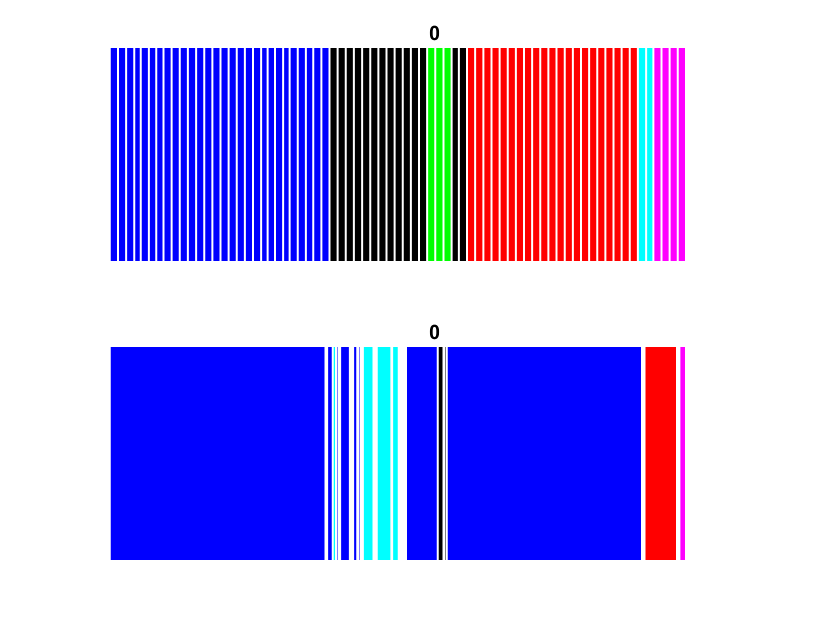

clf;
showSegBar(segResult.s, segResult.G, [1 2 1 1], 1, -1, '0');
showSegBar(GTs, GTG, [1 2 1 2], 1, -1, '0');